# SIM.8. Proportional Integral Design

a = 3.6345;
b = 68.5131;

zeta = - log(1.5/100) / sqrt(pi^2 + log(1.5/100)^2)

zeta = 0.8007

w_n = a/zeta

w_n = 4.5389

w = w_n*sqrt(1-zeta^2)

w = 2.7188


s_d = -a + w*1i;

phi_ULG = angle(b / (s_d + a));
phi_PI = -pi - phi_ULG;
z_PI = a + w/tan(phi_PI + angle(s_d))

z_PI = 5.6683


G_c = (s_d+z_PI)/s_d;
G_p = (b/(s_d+a));
K = abs(1/(G_c*G_p))

K = 0.0530

Gp = zpk([],-3.6029,70.3494) % define the plant TF as an object

Gp =
 
   70.349
  ---------
  (s+3.603)
 
Continuous-time zero/pole/gain model.
Model Properties


Gc = zpk(-5.6263,0, 1) % define the compensator TF

Gc =
 
  (s+5.626)
  ---------
      s
 
Continuous-time zero/pole/gain model.
Model Properties


H = zpk([], [], 1); % define the sensor TF
K = 0.0512;

OLTF = Gc*Gp*H; % blocks in cascade
CLTF = feedback(K*Gc*Gp,H) % negative feedback loop: forward path K*Gc*Gp & feedback H

CLTF =
 
     3.6019 (s+5.626)
  ----------------------
  (s^2 + 7.205s + 20.27)
 
Continuous-time zero/pole/gain model.
Model Properties



[y,tOut] = step(CLTF, 2); % unit step on CLTF
S = stepinfo(CLTF); % calculate step response info
T_s = S.SettlingTime;
OS = S.Overshoot;
fprintf('PI Controller:\n T_s=%f s\n OS=%f \n',T_s,OS)

PI Controller:
 T_s=1.078542 s
 OS=3.124585 


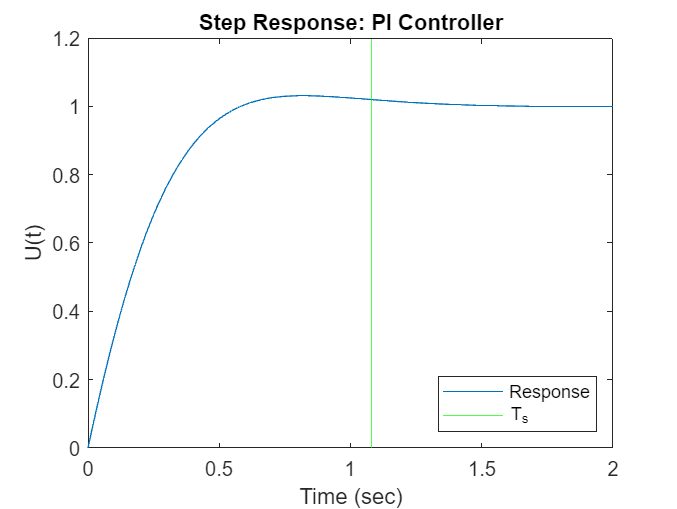


figure; clf;
plot(tOut, y)
xline(S.SettlingTime, 'g')
title("Step Response: PI Controller")
xlabel("Time (sec)")
ylabel("U(t)")
legend("Response", "T_s", "Location", "southeast")

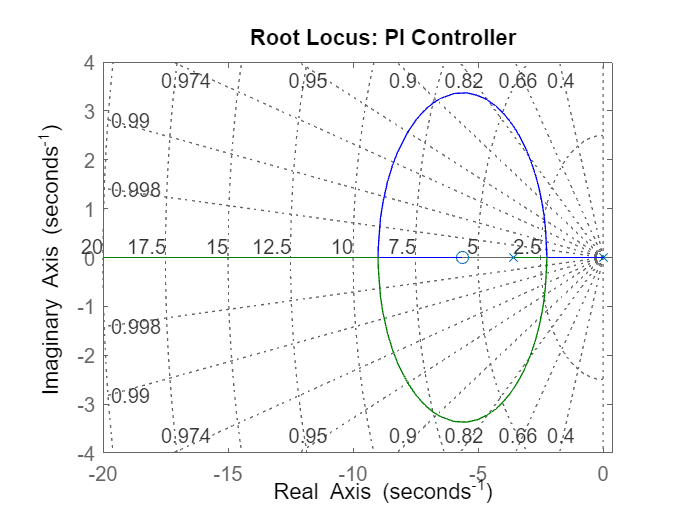


figure; clf;
rlocus(OLTF); % generate the RL for positive K
title("Root Locus: PI Controller")
sgrid; % overlay a grid in polar coordinates

axis; % adjust ranges along x and y axes

r = 45; % rad/s

% run the simulation
out = sim('PI_Controller', 2);

F_v = mean(out.Y.Data(end-10:end)) % calculate final value

F_v = 45.0031


t = out.Y.Time(out.Y.Data >= 1.02*F_v); % calculate times above -2% final value

T_s = t(end)

T_s = 1.0536


u0 = out.u.Data(1) % initial input voltage

u0 = 2.3040


SSE = 45 - F_v % calculate steady state error

SSE = -0.0031


OS = (findpeaks(out.Y.Data) - F_v) / F_v

OS = 0.0299


peak_input = findpeaks(out.u.Data)

peak_input = 2.8050

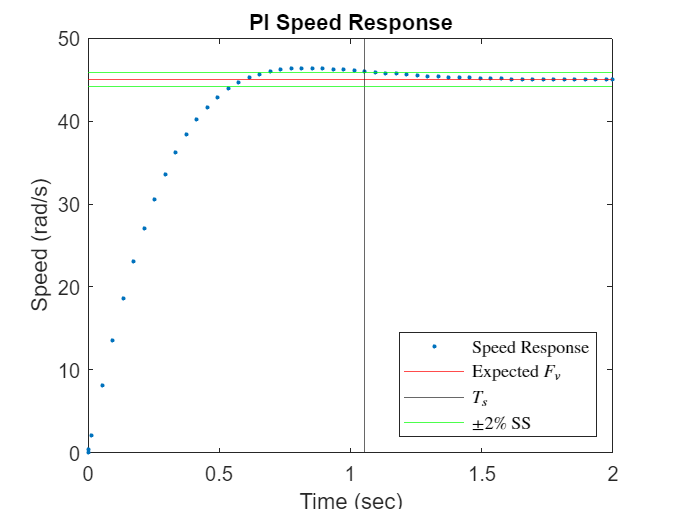

% plot speed response
plot(out.Y.Time, out.Y.Data, '.')
yline(45, 'r')
xline(T_s)
yline(F_v * 0.98, 'g')
%ylim([0 50])
yline(F_v * 1.02, 'g')
title("PI Speed Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend({"Speed Response", "Expected $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

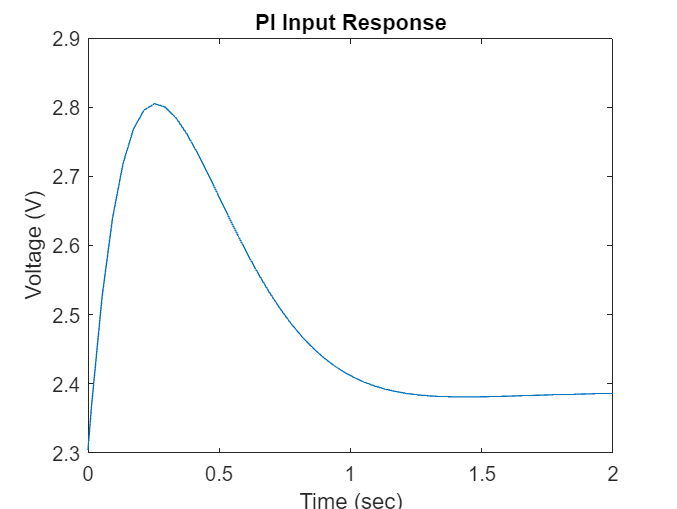


% plot input response
plot(out.u.Time, out.u.Data)
title("PI Input Response")
xlabel("Time (sec)")
ylabel("Voltage (V)")

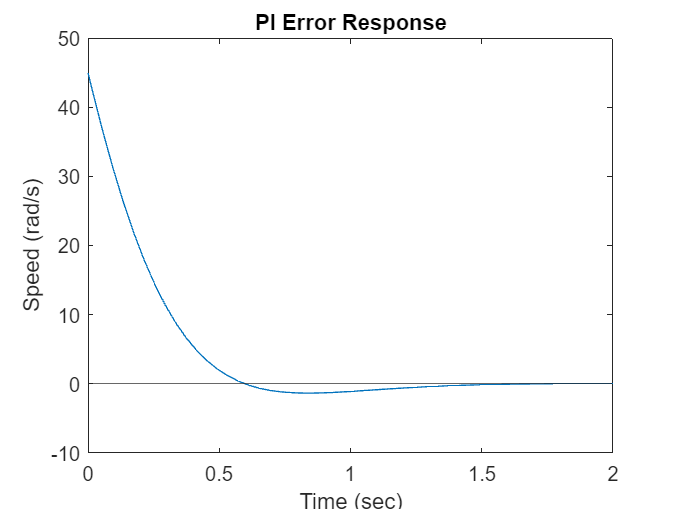


% plot error response
plot(out.u.Time, out.e.Data)
yline(0)
title("PI Error Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")